# **[2024-1 디지털제어 MATLAB 예제] **

# **Unit 3-A: Ch. 2. Discrete-time Systems and the Z-transforms - Part B**

- 본 파일은 2024년 1학기 서울시립대학교 전자전기컴퓨터공학부 디지털제어 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 조교

- **교과목 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- MATLAB version : 2023a 이상 (2022b 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

clc; clear all; close all;

#### 문제 1. Delay operator를 이용한 Simulink 환경에서의 이산시간 시스템 구현

이번 문제에서는 Simulink 환경에서 delay operator만을 이용하여 이산시간 시스템을 구현하는 방식에 대해 살펴보겠습니다. 

다음의 예제를 생각합시다.


$$y^d(k+2)-1.7y^d(k+1)+0.72y^d(k)=u^d(k)$$


(여기서 $u^d(k)$는 입력, $y^d(k)$는 출력이며, 초기값은 $y^d(0)=1$, $y^d(1)=2$로 주어졌다고 합시다.)

위의 이산시간 시스템은 Simulink 환경에서 다양한 방식으로 구현이 가능한데, 이 중 문제 1에서는 delay operator를 활용하여 구현하는 방식을 알아보겠습니다. 

open('sim_Prob1.slx');

Delay operator는, Simulink의 "라이브러리 브라우저" 중 [Simulink]-[Discrete] 카테고리에서 확인할 수 있습니다.

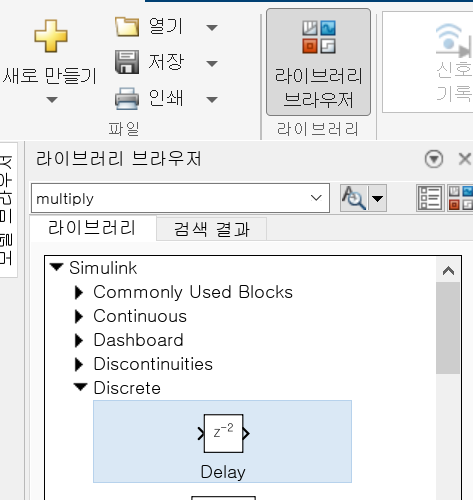

이를 Simulink의 빈 공간에 옮기면 (이산시간 영역에서) delay operator 역할을 하는 아래의 블록을 생성할 수 있습니다.

(Unit delay operator가 필요하기 때문에, "지연길이"를 1로 지정해줍시다. "초기조건"도 수정이 필요한데, 이 부분은 아래에서 다시 언급하겠습니다.)

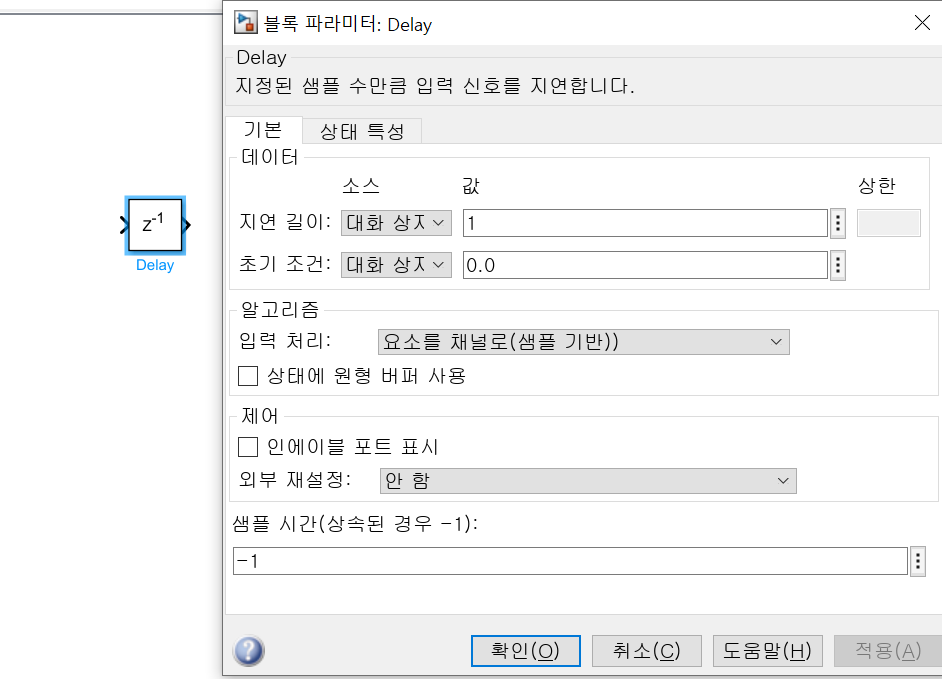

이제 이산시간 시스템을 설명하는 차분 방정식(difference equation)을 


$$y^d(k+2)=-1.7y^d(k+1)-0.72y^d(k)+u^d(k)$$


의 형태로 다시 기술하고, 이를 Simulink 환경에서 다음과 같이 구현합시다.

(여기서 입력 $u^d(k)$는 unit step 함수입니다.)

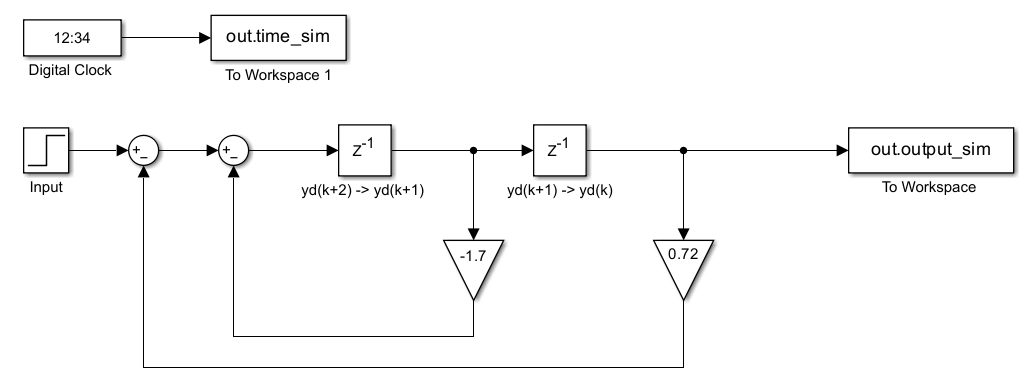

여기서 2개의 delay operator는 각각 $y^d(k+1)$과 $y^d(k)$를 출력으로 하며, 각 블록의 초기조건을 $y^d(1)$과 $y^d(0)$로 하였습니다. 

이제 아래와 같이 시뮬레이션을 구동하고 결과를 살펴봅시다. 

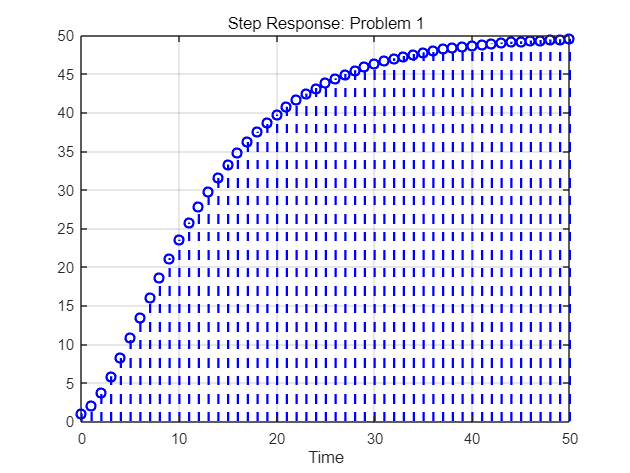

N = 50;
sim('sim_Prob1.slx');
simout = ans;
time_sim1 = simout.time_sim;
output_sim1 = simout.output_sim;

figure();
stem(time_sim1,output_sim1,'--b','LineWidth',1.5);
grid on;
xlim([0,N]);
title('Step Response: Problem 1')

xlabel('Time');

#### 문제 2. MATLAB/Simulink 환경에서 이산시간 시스템의 상태변수 모델 구현

open('sim_Prob2.slx');

이제 문제 1의 이산시간 시스템을 다음의 상태변수 모델로 구현해봅시다. 


$$x^d(k+1)=A^d x^d(k)+B^d u^d(k)$$



$$y^d(k) = C^d x^d(k) + D^d u^d(k)$$


우선 첫 번째로, 상태변수 $x^d(k)$를 아래와 같이 정의합시다. 


$$x^d(k):=\left[\matrix{ y^d(k) \cr y^d(k+1) }\right]$$


위의 상태변수에 대하여, 문제 1의 이산시간 시스템을 표현하는 상태변수 모델은 다음의 $(A^d, B^d, C^d, D^d)$로 구성됩니다. 

Ad = [0 1; -0.72 1.7];
Bd = [0; 1];
Cd = [1 0];
Dd = 0;

위의 상태변수 모델은 MATLAB 환경에서 ss 함수를 사용하여 상태변수 모델 객체로 지정할 수도 있습니다.

sys = ss(Ad,Bd,Cd,Dd,-1);

이제 Simulink로 돌아가서, "라이브러리 브라우저" 중 [Discrete]-[Discrete State-Space] 블록을 불러옵니다.

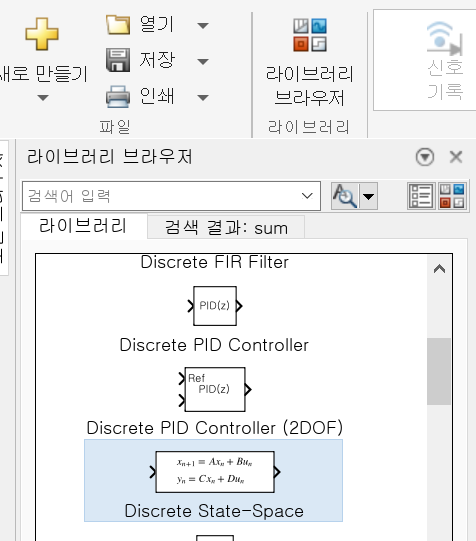

이 블록을 불러온 후 더블클릭하면 아래의 창이 뜨는데, 여기에 필요한 정보들을 기입합니다.

이 중 "초기 조건"은 상태변수의 초기값


$$x^d(0)=\left[\matrix{ y^d(0) \cr y^d(1) }\right] = \left[\matrix{ 1 \cr 2 }\right]$$


을 의미하므로, 

xd0 = [1; 2];

를 대입해주면 됩니다.

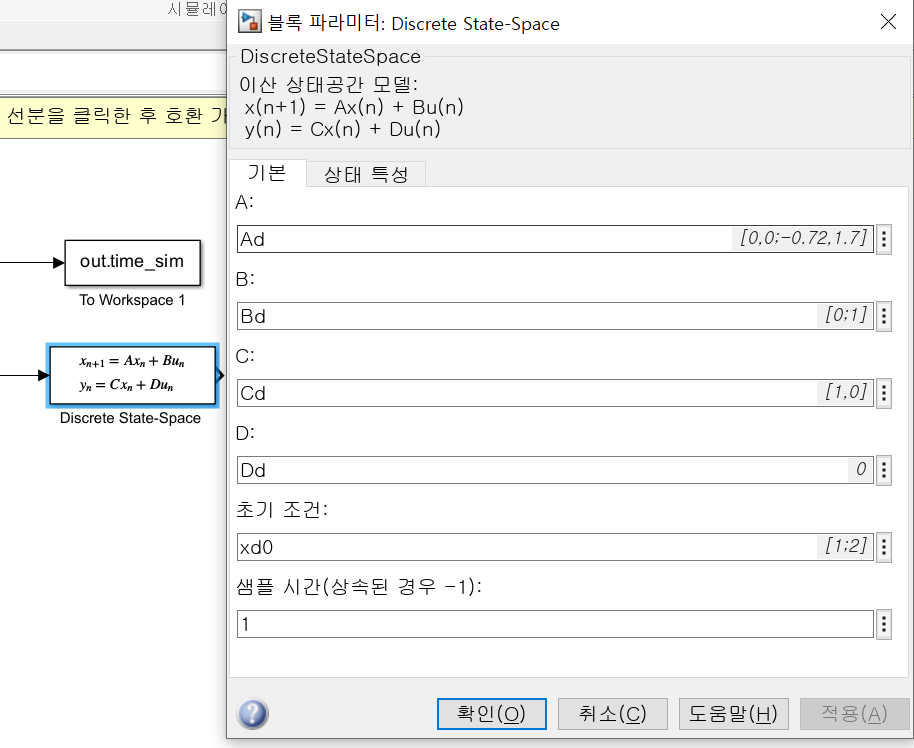

이제 위의 Simulink 파일을 구동하여, Problem 1의 결과와 비교해봅시다.

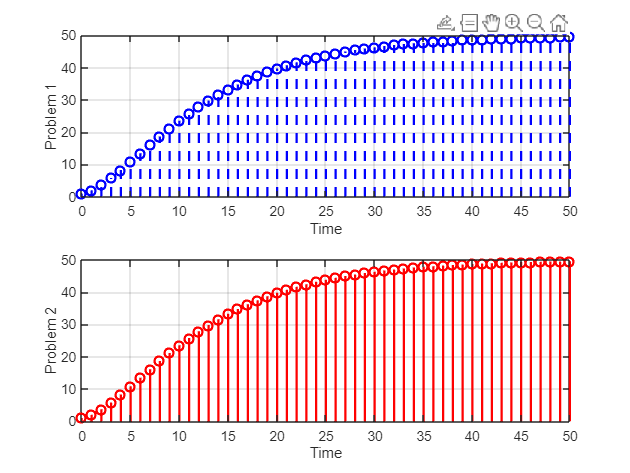

sim('sim_Prob2.slx');
simout = ans;
time_sim2 = simout.time_sim;
output_sim2 = simout.output_sim;

figure();
subplot(2,1,1);
stem(time_sim1,output_sim1,'--b','LineWidth',1.5);
grid on;
xlim([0,N]);
xlabel('Time');
ylabel('Problem 1');
hold on

subplot(2,1,2);
stem(time_sim2,output_sim2,'r','LineWidth',1.5);
grid on;
xlim([0,N]);
xlabel('Time');
ylabel('Problem 2');

#### 문제 3. For 문으로 이산시간 시스템 구현

문제 3에서는 문제 2의 상태변수 모델을 Simulink의 도움을 받지 않고 구현 및 모의실험하는 방법에 대해 살펴보도록 하겠습니다. 

(이는 이후 (차분 방정식으로 표현되는) 제어 알고리즘을 마이크로프로세서 등에 직접 구현하는 등의 작업을 대비하기 위해 필요합니다.)

이를 위해 일단 상태변수, 입력변수 및 출력변수를 초기화합시다. 

stateVar = [1; 2];
inputVar = 1;
outputVar = Cd * stateVar + Dd * inputVar;

모의실험과는 별도로, 결과를 저장할 공간을 따로 만들겠습니다. 

time_sim3 = [];
output_sim3 = [];

이제 MATLAB 환경에서 for 문을 이용하여 아래와 같이 상태변수 모델을 구현합시다. 

for k = 0:N
    time_sim3 = [time_sim3; k];
    output_sim3 = [output_sim3; outputVar];

    inputVar = 1; % Unit step 입력
    stateVar_plus = Ad * stateVar + Bd * inputVar;
    outputVar = Cd * stateVar + Dd * inputVar;

    stateVar = stateVar_plus;
end

이제 문제 1 ~ 문제 3의 모든 결과를 비교해봅시다.

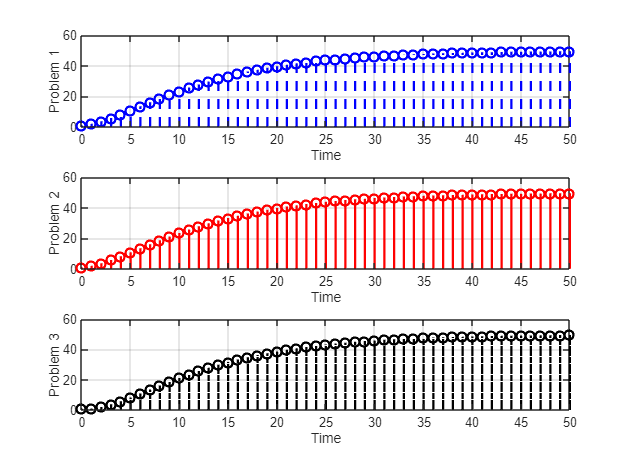

figure();
subplot(3,1,1);
stem(time_sim1,output_sim1,'--b','LineWidth',1.5);
grid on;
xlim([0,N]);
xlabel('Time');
ylabel('Problem 1');
hold on

subplot(3,1,2);
stem(time_sim2,output_sim2,'r','LineWidth',1.5);
grid on;
xlim([0,N]);
xlabel('Time');
ylabel('Problem 2');

subplot(3,1,3);
stem(time_sim3,output_sim3,'-.k','LineWidth',1.5);
grid on;
xlim([0,N]);
xlabel('Time');
ylabel('Problem 3');